# Si-CLASH Master Synchronizer Live Explorer (CP6, Blind Quadrant Recovery & Section 1.3)

This interactive Live Script runs the complete end-to-end Transmitter, Physical Channel, and Blind Three-Stage Receiver Synchronization pipeline.

clear; clc; close all;
cur_file = mfilename('fullpath');
if ~isempty(cur_file)
    search_dir = fileparts(cur_file);
else
    search_dir = pwd;
end
for depth = 1:4
    if exist(fullfile(search_dir, 'setup_project.m'), 'file')
        addpath(search_dir);
        break;
    end
    search_dir = fileparts(search_dir);
end
setup_project(false);

[SETUP] Synchronizer paths added and .mlx Live Scripts compiled in live_scripts/.


## 1. Configure Full-Burst Simulation (QPSK or 16-QAM)

Set the modulation format, normalisation mode, SNR definition, and channel impairments.

cfg = get_default_config();
cfg.mod_type        = 1;            % 0 = QPSK, 1 = 16-QAM
cfg.norm_mode       = 'peak';       % 'peak' (interim default) or 'rms' [Part 0a]
cfg.snr_def         = 'esn0';       % 'esn0' (symbol-rate Es/N0) or 'sample' (oversampled SNR) [Part 1b]
cfg.str.interp_type = 'cubic';      % 'cubic' (default) or 'parabolic'
cfg.snr_dB          = 18.0;         % Requested SNR / Es/N0 (dB)
cfg.tau_offset      = 0.35;         % Fractional timing skew in Ts
cfg.cfo_norm        = 0.065;        % +6.5% Rsym Carrier Frequency Offset
cfg.phase_offset    = 115*(pi/180); % Arbitrary initial carrier phase (tests quadrant recovery)
cfg.preamble_type   = 'q4q2_q1';    % Three-phase blind preamble (Q3 never transmitted)

## 2. Generate Burst Frame, RRC Pulse Shaping & Physical Channel Impairments

Build the burst frame, measure actual channel Es/N0, and quantise to Q1.11.

preamble_syms = generate_preamble(cfg.preamble_type, cfg.N_preamble, cfg);
[payload_syms, const] = generate_payload(cfg.mod_type, cfg.N_payload, cfg.seed, cfg.norm_mode);
tx_syms     = [preamble_syms; payload_syms];
tx_waveform = pulse_shape_rrc(tx_syms, cfg.rrc_alpha, cfg.rrc_span, cfg.sps, 'tx');
meas_esn0   = measure_es_n0(tx_waveform, cfg);
[rx_q11, ch_info] = apply_channel_impairments(tx_waveform, cfg);
in_valid    = true(size(rx_q11));

## 3. Run Blind Top-Level Synchronizer & Print PASS/FAIL Specification Report

Execute the blind receiver, print [PASS]/[FAIL] beside every spec, and plot diagnostics.

rx_out  = run_synchronizer_top(rx_q11, in_valid, cfg, []);
metrics = compute_evm_and_metrics(rx_out, payload_syms, cfg, meas_esn0);

print_spec_report(rx_out, metrics, cfg, ch_info);

  Si-CLASH SYNCHRONIZATION UNIT SPECIFICATION REPORT (16-QAM, norm_mode='peak', snr_def='esn0', Req SNR=18.0 dB, Meas Es/N0=18.13 dB)
  Specification / Definition                   | Measured Value                     | Target Limit | Status
--------------------------------------------------------------------------------------------------------
  EVM (RMS-ref,  snr_def=esn0, norm=peak)      | Meas=14.34%, Flr=12.40%, Exc=7.21% | <=   8.00 %  | [FAIL]
  EVM (Peak-ref, snr_def=esn0, norm=peak)      | Meas=10.63%, Flr=9.19%, Exc=5.34%  | <=   8.00 %  | [FAIL]
  STR Timing Jitter RMS (R.111)                |                          0.0201 Ts | <= 0.0200 Ts | [FAIL]
  STR Lock Time (R.112)                        |                             37 sym | <=    150 sym | [PASS]
  Coarse C

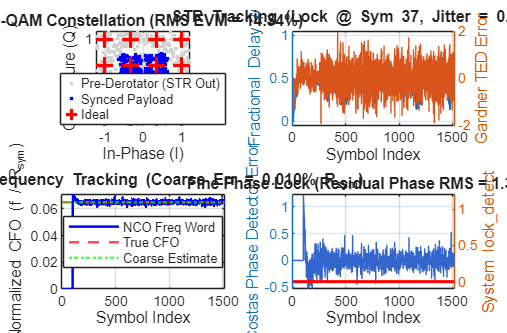

plot_sync_diagnostics(rx_out, metrics, cfg);

## 4. Section 1.3 Open Experiment: Interpolator Tap vs. Derotator Tap

Compare coarse CFO estimation accuracy at both candidate tap locations.

tap_modes = {'interpolator', 'derotator'};
for m = 1:numel(tap_modes)
    cfg_exp = cfg;
    cfg_exp.coarse.tap_point = tap_modes{m};
    out_exp = run_synchronizer_top(rx_q11, in_valid, cfg_exp, []);
    met_exp = compute_evm_and_metrics(out_exp, payload_syms, cfg_exp, meas_esn0);
    cfo_st  = 'FAIL'; if met_exp.pass.coarse_cfo, cfo_st = 'PASS'; end
    evm_st  = 'FAIL'; if met_exp.pass.evm_rms,    evm_st = 'PASS'; end
    disp(sprintf('[Tap Point: %-12s] Coarse CFO Err = %.4f%% Rsym [%s] | RMS EVM = %.2f%% [%s]', ...
        tap_modes{m}, met_exp.coarse_cfo_err_pct, cfo_st, met_exp.evm_rms_pct, evm_st));
end

[Tap Point: interpolator] Coarse CFO Err = 0.0097% Rsym [PASS] | RMS EVM = 14.34% [FAIL]
[Tap Point: derotator   ] Coarse CFO Err = 0.0097% Rsym [PASS] | RMS EVM = 14.34% [FAIL]
